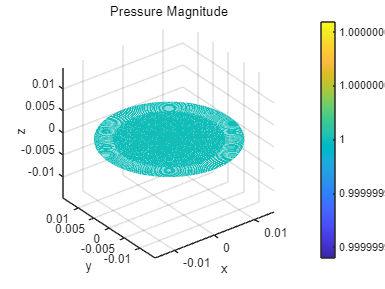

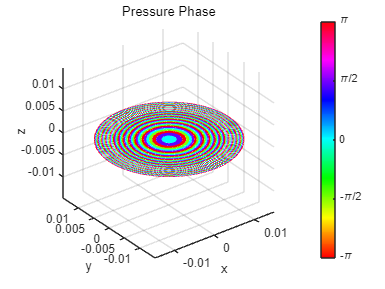

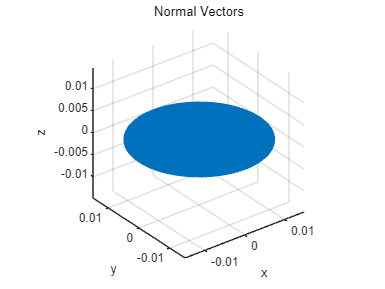

clc; close; clear;

% load('freq_sweep_0816_10.mat')
% load('freq_sweep_0816_11.mat')

% v_sens=max_v./input_v;
% sens=mySensitivity('HNR500_1979',f_list');
% p_sens=v_sens'./sens;

transducer_info = [];
transducer_info.Frequency = 5e6;
transducer_info.Pressure = 1;
transducer_info.Phase = 0;

transducer_info.focal_length = 30e-3;

% transducer_info.chan_list = 1:6;

% transducer_info.Length_x = 5e-3;
% transducer_info.Length_y = 10e-3;

% transducer_info.Radius = 5e-3;

transducer_info.Type = 'CMUT_30mm';

transducer_object = PFC_Make3DTransducer(transducer_info);
PFC_DrawTransducer3D(transducer_object);

input_source = [];
input_source.Type = 'frequency';
reading_f = 5e6; % [Hz]
input_source.reading_list = reading_f;
%% Simulation Space
% reading_pos_x = -5e-3 : 0.1e-3 : 5e-3;          % Simulation Area
% reading_pos_y = -4e-3 : 0.1e-3 : 4e-3;          % Simulation Area
% reading_pos_z = 5e-3 : 0.1e-3 : 60e-3;          % Simulation Area
reading_pos_x = -15e-3:0.05e-3:15e-3;          % Simulation Area
reading_pos_y = 0;          % Simulation Area
reading_pos_z = 30e-3;       % Simulation Area
%% Run Frequency Domain Simulation
% xyz plane
[Pressure_dxyz] = ...
PFC_CalculatePressureField(...
transducer_object, input_source,...                 % tx setting
reading_pos_x, reading_pos_y, reading_pos_z,'split', 5);

Started at 2023-12-19 15:27:25
Finished at 2023-12-19 15:28:39
Progressed time : 00:01:13


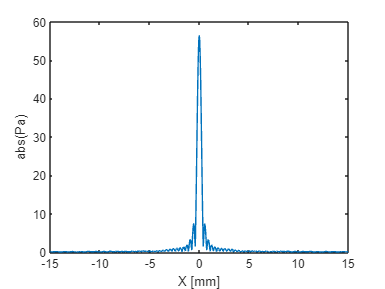


Pressure_dxyz_i = abs(squeeze(Pressure_dxyz));

% surface_p_sens=p_sens.*Pressure_dxyz_i;

figure
plot(reading_pos_x*1e3,Pressure_dxyz_i)
xlabel('X [mm]')
ylabel('abs(Pa)')


% figure
% imagesc(reading_pos_x*1e3,reading_pos_y*1e3,Pressure_dxyz_i)
% colorbar
% xlabel('X [mm]')
% ylabel('Y [mm]')
% ax = gca;
% ax.YDir = 'normal';